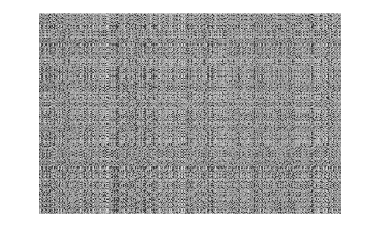

clear
a=imread('pears.png');  %保密图像
b=imread('peppers.png');     %载体图像
a=rgb2gray(a);
b=rgb2gray(b);
ws1=size(a);
b1=imresize(b,ws1);  %将载体图像调整大小与保密图像一样
key=-0.400001;  %密钥，即混沌序列的初始值
L=max(ws1);
x(1)=key;y(1)=key;
alpha=1.4;beta=0.3;
for i=1:L-1   %生成两个混沌序列
    x(i+1)=1-alpha*x(i)^2+y(i);
    y(i+1)=beta*x(i);
end
x(min(ws1)+1:end)=[];    %删除x后面一部分元素
[sx,ind1]=sort(x);
[sy,ind2]=sort(y);  %对混沌系列从小到大排序
ea(ind1,ind2)=a;    %打乱，生成加密图像
imshow(ea)

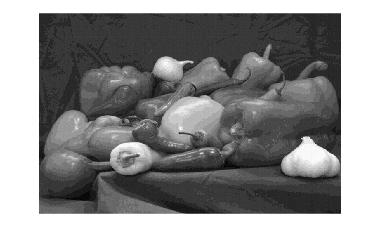

b2=bitand(b1,240); %载体图像与11110000（2）=240（10）按位与运算
ea2=bitand(ea,240);
ea2=ea2/16;   %加密图像高4位移到低4位
da=bitor(b2,ea2);  %加密图像嵌入载体图像的低4位
imshow(da)

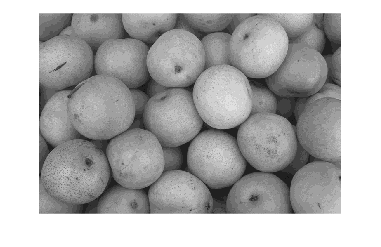

%加密提取
da2=bitand(da,15)*16;  %提取合成图像中加密图像的高4位15（10）=00001111（2）
da3=da2(ind1,ind2);  %解密
imshow(da3)